% =========================================================================
% DIAGNÓSTICO DE MAPEO: Ajustes Geométricos de Sensor y Log-Odds
% =========================================================================
clear; clc; close all;

%% 0. CONFIGURACIÓN DEL TEST
% 'true' para mapear con Ground Truth / 'false' para mapear con Odometría
USAR_GROUND_TRUTH = false; 

%% 1. Cargar el archivo ROSBAG
filePath = 'mir_basics_20251210_114529.bag'; % Reemplaza con tu archivo
disp('Abriendo archivo rosbag...');

Abriendo archivo rosbag...


bag = rosbag(filePath);

bagOdom = select(bag, 'Topic', '/odom');
bagScan = select(bag, 'Topic', '/scan');
bagGT   = select(bag, 'Topic', '/base_pose_ground_truth');

time_odom = bagOdom.MessageList.Time;
time_scan = bagScan.MessageList.Time;
time_gt   = bagGT.MessageList.Time;

disp('Leyendo mensajes del rosbag...');

Leyendo mensajes del rosbag...


odomMsgs = readMessages(bagOdom, 'DataFormat', 'struct');
scanMsgs = readMessages(bagScan, 'DataFormat', 'struct');
gtMsgs   = readMessages(bagGT, 'DataFormat', 'struct');

%% 1.1 Extraer y Alinear Poses (GT y Odometría)
total_scan_msgs = length(scanMsgs);

% --- Alinear Ground Truth ---
[~, first_gt_idx] = min(abs(time_gt - time_scan(1)));
start_gt_pos = [gtMsgs{first_gt_idx}.Pose.Pose.Position.X, gtMsgs{first_gt_idx}.Pose.Pose.Position.Y];
start_gt_yaw = quat2yaw_local(gtMsgs{first_gt_idx}.Pose.Pose.Orientation);

% --- Alinear Odometría ---
[~, first_odom_idx] = min(abs(time_odom - time_scan(1)));
start_odom_pos = [odomMsgs{first_odom_idx}.Pose.Pose.Position.X, odomMsgs{first_odom_idx}.Pose.Pose.Position.Y];
start_odom_yaw = quat2yaw_local(odomMsgs{first_odom_idx}.Pose.Pose.Orientation);

%% 2. Inicialización del Mapa de Ocupación Log-Odds
map_res = 0.1; % Resolución de 5 cm
x_min = -20; x_max = 20; 
y_min = -20; y_max = 20;
cols = round((x_max - x_min) / map_res);
rows = round((y_max - y_min) / map_res);

log_odds_map = zeros(rows, cols); 

p_occ = 0.98;  %0.98 fue el mejor
p_free = 0.3;  %0.3 fue el más ótpimo para que no borrara de más
l_occ = log(p_occ / (1 - p_occ));
l_free = log(p_free / (1 - p_free));

l_max = 10;
l_min = -10;

trajectory_test = zeros(total_scan_msgs, 3);

%% 3. Bucle Principal de Construcción de Mapa
disp(['Iniciando mapeo usando GT = ', mat2str(USAR_GROUND_TRUTH)]);

Iniciando mapeo usando GT = false



for i = 1:total_scan_msgs
    current_time = time_scan(i);
    scan = scanMsgs{i};

    % --- A. OBTENER POSE DEL ROBOT (BASE_LINK) ---
    if USAR_GROUND_TRUTH
        [~, idx] = min(abs(time_gt - current_time));
        msg = gtMsgs{idx};
        rob_x = msg.Pose.Pose.Position.X - start_gt_pos(1);
        rob_y = msg.Pose.Pose.Position.Y - start_gt_pos(2);
        yaw_raw = quat2yaw_local(msg.Pose.Pose.Orientation);
        rob_yaw = wrapToPi(yaw_raw - start_gt_yaw);
    else
        [~, idx] = min(abs(time_odom - current_time));
        msg = odomMsgs{idx};
        rob_x = msg.Pose.Pose.Position.X - start_odom_pos(1);
        rob_y = msg.Pose.Pose.Position.Y - start_odom_pos(2);
        yaw_raw = quat2yaw_local(msg.Pose.Pose.Orientation);
        rob_yaw = wrapToPi(yaw_raw - start_odom_yaw);
    end
    
    trajectory_test(i, :) = [rob_x, rob_y, rob_yaw];

    % --- B. AJUSTES GEOMÉTRICOS DEL SENSOR (TF) ---
    % *** MODIFICA ESTOS VALORES SI EL MAPA SIGUE DISTORSIONADO ***
    laser_offset_x   = 0.4296;    % Desplazamiento del láser hacia adelante/atrás (ej. 0.2 m)
    laser_offset_y   = 0.2358;    % Desplazamiento lateral
    laser_offset_yaw = 0.7854;    % Rotación del láser (Prueba pi/2, -pi/2 o pi si está rotado)
    invertir_angulos = 1;      % Cambia a -1 si el mapa se dibuja como un espejo
    
    % Posición del láser en el mundo
    laser_x = rob_x + laser_offset_x * cos(rob_yaw) - laser_offset_y * sin(rob_yaw);
    laser_y = rob_y + laser_offset_x * sin(rob_yaw) + laser_offset_y * cos(rob_yaw);
    laser_yaw = wrapToPi(rob_yaw + laser_offset_yaw);
    

    % --- C y D. PROCESAMIENTO Y ACTUALIZACIÓN DE MAPA MEJORADO ---
    all_ranges = double(scan.Ranges);
    angle_min = double(scan.AngleMin);
    angle_inc = double(scan.AngleIncrement);
    all_angles = angle_min + (0:length(all_ranges)-1)' * angle_inc;
    
    range_min = double(scan.RangeMin);
    r_max_mapping = 7.0; % Límite de confianza del láser para mapear, estaba en 10
    
    laser_x_grid = round((laser_x - x_min) / map_res) + 1;
    laser_y_grid = round((laser_y - y_min) / map_res) + 1;
    
    for k = 1:length(all_ranges)
        r = all_ranges(k);
        a = all_angles(k);
        
        % 1. Ignorar lecturas defectuosas o que golpean el chasis del propio robot
        if isnan(r) || r < range_min
            continue;
        end
        
        % 2. Determinar si es un impacto real o un rayo que no chocó con nada (infinito)
        es_impacto_valido = isfinite(r) && r <= r_max_mapping;
        
        % Si el rayo va más allá de nuestro límite, solo trazamos hasta r_max_mapping para limpiar
        r_trazado = min(r, r_max_mapping); 
        
        % 3. Coordenadas del extremo del rayo
        end_x = laser_x + r_trazado * cos(laser_yaw + (a * invertir_angulos));
        end_y = laser_y + r_trazado * sin(laser_yaw + (a * invertir_angulos));
        
        end_x_grid = round((end_x - x_min) / map_res) + 1;
        end_y_grid = round((end_y - y_min) / map_res) + 1;
        
        % Trazado del rayo (Bresenham)
        [ray_x, ray_y] = get_ray_cells(laser_x_grid, laser_y_grid, end_x_grid, end_y_grid);
        
        % Filtrar celdas fuera del mapa
        valid_ray_idx = ray_x > 0 & ray_x <= cols & ray_y > 0 & ray_y <= rows;
        ray_x = ray_x(valid_ray_idx);
        ray_y = ray_y(valid_ray_idx);
        
        if isempty(ray_x); continue; end
        
        lin_idx = sub2ind([rows, cols], ray_y, ray_x);
        
        % 4. Actualización Log-Odds Inteligente
        if es_impacto_valido
            % Si chocó: Todo el rayo es libre, excepto la última celda que es obstáculo
            if length(lin_idx) > 1
                log_odds_map(lin_idx(1:end-1)) = log_odds_map(lin_idx(1:end-1)) + l_free;
            end
            log_odds_map(lin_idx(end)) = log_odds_map(lin_idx(end)) + l_occ;
        else
            % Si NO chocó (infinito): TODO el rayo trazado cuenta como espacio libre
            log_odds_map(lin_idx) = log_odds_map(lin_idx) + l_free;
        end
    end


    % % --- C. FILTRADO DE LECTURAS DEL LIDAR ---
    % all_ranges = double(scan.Ranges);
    % angle_min = double(scan.AngleMin);
    % angle_inc = double(scan.AngleIncrement);
    % all_angles = angle_min + (0:length(all_ranges)-1)' * angle_inc;
    % 
    % % Leer los límites reales desde el mensaje ROS
    % range_min = double(scan.RangeMin);
    % range_max = double(scan.RangeMax);
    % r_max_mapping = min(range_max, 15.0); % Límite seguro para no trazar rayos infinitos
    % 
    % valid_scan_idx = isfinite(all_ranges) & all_ranges >= range_min & all_ranges <= r_max_mapping;
    % r_valid = all_ranges(valid_scan_idx);
    % a_valid = all_angles(valid_scan_idx);
    % 
    % % Índice del LÁSER en la cuadrícula (desde aquí salen los rayos)
    % laser_x_grid = round((laser_x - x_min) / map_res) + 1;
    % laser_y_grid = round((laser_y - y_min) / map_res) + 1;
    % 
    % % --- D. ACTUALIZACIÓN DEL MAPA ---
    % for k = 1:length(r_valid)
    %     % Coordenadas del obstáculo usando el frame del LÁSER
    %     obs_x = laser_x + r_valid(k) * cos(laser_yaw + (a_valid(k) * invertir_angulos));
    %     obs_y = laser_y + r_valid(k) * sin(laser_yaw + (a_valid(k) * invertir_angulos));
    % 
    %     obs_x_grid = round((obs_x - x_min) / map_res) + 1;
    %     obs_y_grid = round((obs_y - y_min) / map_res) + 1;
    % 
    %     % Trazado de rayos
    %     [ray_x, ray_y] = get_ray_cells(laser_x_grid, laser_y_grid, obs_x_grid, obs_y_grid);
    % 
    %     % Filtrar rayos fuera del mapa
    %     valid_ray_idx = ray_x > 0 & ray_x <= cols & ray_y > 0 & ray_y <= rows;
    %     ray_x = ray_x(valid_ray_idx);
    %     ray_y = ray_y(valid_ray_idx);
    % 
    %     if isempty(ray_x); continue; end
    % 
    %     lin_idx = sub2ind([rows, cols], ray_y, ray_x);
    % 
    %     % Log-odds: espacio libre
    %     if length(lin_idx) > 1
    %         log_odds_map(lin_idx(1:end-1)) = log_odds_map(lin_idx(1:end-1)) + l_free;
    %     end
    %     % Log-odds: obstáculo
    %     log_odds_map(lin_idx(end)) = log_odds_map(lin_idx(end)) + l_occ;
    % end
    % 
    % if mod(i, 200) == 0
    %     fprintf('Procesados %d de %d scans...\n', i, total_scan_msgs);
    % end
end
disp('Mapeo Finalizado.');

Mapeo Finalizado.


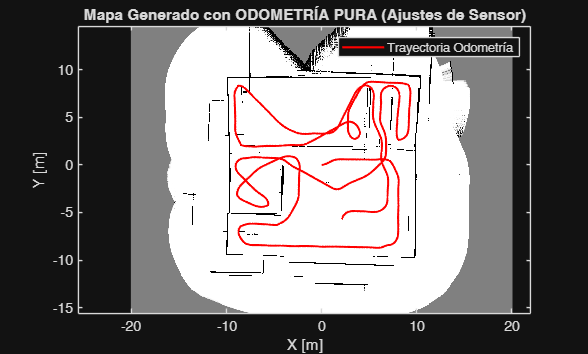


%% 4. Visualización
log_odds_map = max(min(log_odds_map, l_max), l_min);
prob_map = 1 - (1 ./ (1 + exp(log_odds_map)));
%----------------------------------------------
% 
% % Convertir a imagen binaria temporalmente para limpiar ruido pequeño
% % (elimina grupos de obstáculos menores a 5 píxeles)
% map_limpio = prob_map > 0.65; % Umbral para considerar que algo es pared
% map_limpio = bwareaopen(map_limpio, 5); % Requiere Image Processing Toolbox
% 
% % Restaurar el mapa probabilístico, pero borrando el ruido filtrado
% prob_map(prob_map > 0.65 & ~map_limpio) = 0.5;
%----------------------------------------------
figure('Name', 'Diagnóstico de Mapeo Ajustado', 'NumberTitle', 'off');
imagesc([x_min x_max], [y_min y_max], 1 - prob_map); 
colormap(gray); 
axis equal xy; 
hold on;
plot(trajectory_test(:,1), trajectory_test(:,2), 'r-', 'LineWidth', 1.5);

if USAR_GROUND_TRUTH
    title('Mapa Generado con GROUND TRUTH (Ajustes de Sensor)');
    legend('Trayectoria GT');
   
else
    title('Mapa Generado con ODOMETRÍA PURA (Ajustes de Sensor)');
    legend('Trayectoria Odometría');

end
xlabel('X [m]'); ylabel('Y [m]');


%% ========================================================================
% FUNCIONES AUXILIARES
% =========================================================================
function [x, y] = get_ray_cells(x1, y1, x2, y2)
    n_points = max(abs(x2 - x1), abs(y2 - y1)) + 1;
    x = round(linspace(x1, x2, n_points));
    y = round(linspace(y1, y2, n_points));
end

function yaw = quat2yaw_local(q)
    yaw = atan2(2*(q.W*q.Z + q.X*q.Y), 1 - 2*(q.Y^2 + q.Z^2));
end
